clc;
clear;
close all;

addpath PROPACK;

% fixed model parameter set
tol = 1e-4;
maxiter = 1000;

% parameters for splp
gamma = 4;
p1 = 0.01;
p2 = 0.01;

% parameters for N/F-ADMM
lembda = 300;
mu1 = 0.1;
mu2 = 0.1;
k_max = 500;
t_max = 5;
tol_nf = 1e-5;

% every experiment would be repeated for 10 times
% compute the average and the standard deviation
repeat = 10;

% basic parameters set
% n1 x n2
n1 = 100;
n2 = 100;
n1xn2_vec = [100, 100; 200, 100; 200, 200; 300, 100; 300, 200; 400, 100; 400, 300];

% mu
mu = 0.1;
mu_vec = (0.1: 0.05: 0.5)';

% r
r = 10;
r_vec = (6: 2: 20)';

% sr
sr = 0.5;
sr_vec = (0.5: 0.05: 0.9)';

main part of the code

- change mu

- change r

- change sr

%% 1. change mu
% re_mu_**_vec stores the average value(re) and its std of ** for different mu
% 9 below means there are 9 different mus
re_mu_svt_vec = zeros(9, 2);
re_mu_wnnm_vec = zeros(9, 2);
re_mu_splp_vec = zeros(9, 2);
re_mu_nf_vec = zeros(9, 2);

% record the time
time_mu_svt_vec = zeros(9, 1);
time_mu_wnnm_vec = zeros(9, 1);
time_mu_splp_vec = zeros(9, 1);
time_mu_nf_vec = zeros(9, 1);

% index indicates the index of current mu_change
index = 1;

% fun for different mu_changes
for mu_change = 0.1: 0.05: 0.5
    mu_change
    index

    % define re_**_vec
    re_svt_vec = zeros(repeat, 1);
    re_wnnm_vec = zeros(repeat, 1);
    re_splp_vec = zeros(repeat, 1);
    re_nf_vec = zeros(repeat, 1);
    
    % repeat, return the vec
    for i = 1 : repeat
    
        % generating matrix
        L = normrnd(0, 1, n1, r);
        R = normrnd(0, 1, n2, r);
        N = normrnd(0, 1, n1, n2);
        X = L * R' + mu_change * N;
        
        % sampling matrix(support)
        support = ones(n1, n2);
        Ind = randperm(n1 * n2);
        
        %number of missing values
        EL0 = round(n1 * n2 * (1 - sr));
        
        %random EL0 elements would be set to 0
        support(Ind(1:EL0)) = 0;
    
        % observed matrix
        D = support .* X;
    
        % ||X||_F
        X_fro = max(norm(X, 'fro'), 1);
    
        %% SVT
        % svt parameters
        tao = sqrt(n1 * n2);
        step = 1.2 * sr;
    
        % experiment
        start_svt = tic;
        X_svt = SVT(D, support, tao, step, maxiter, tol);
        time_svt = toc(start_svt);
        % time
        time_mu_svt_vec(index, 1) = time_mu_svt_vec(index, 1) + time_svt;
    
        % re
        re_svt = norm(X_svt - X,'fro') / X_fro;
    
        % fill in the re_svt_vec
        re_svt_vec(i, 1) = re_svt;
    
        %% WNNM
        % wnnm parameters
        C = sqrt(n1 * n2);
    
        % experiment
        start_wnnm = tic;
        [A_WNNM, ~] = WNNM(D, support, C, eps, maxiter, tol);
        time_wnnm = toc(start_wnnm);
        % time
        time_mu_wnnm_vec(index, 1) = time_mu_wnnm_vec(index, 1) + time_wnnm;
    
        % re
        re_wnnm = norm(A_WNNM - X, 'fro') / X_fro;
    
        % fill in the re_wnnm_vec
        re_wnnm_vec(i, 1) = re_wnnm;
    
        %% Sp_lp
        % splp parameters
        % gamma = 1;
        % p1 = 0.1;
        % p2 = 0.2;

        % experiment
        start_splp = tic;
        X_splp = Sp_lp_new(D, support, gamma, p1, p2, maxiter, tol);
        time_splp = toc(start_splp);
        % time
        time_mu_splp_vec(index, 1) = time_mu_splp_vec(index, 1) + time_splp;

        % re
        re_splp = norm(X_splp - X, 'fro') / X_fro;

        % fill in the re_splp_vec
        re_splp_vec(i, 1) = re_splp;

        %% N/F
        % experiment
        start_nf = tic;
        X_nf = NF(D, support, lembda, mu1, mu2, k_max, t_max, tol_nf);
        time_nf = toc(start_nf);
        % time
        time_mu_nf_vec(index, 1) = time_mu_nf_vec(index, 1) + time_nf;

        % re
        re_nf = norm(X_nf - X, 'fro') / X_fro;

        %fill in the re_nf_vec
        re_nf_vec(i, 1) = re_nf;

    end

    % fill in the average re
    re_mu_svt_vec(index, 1) = mean(re_svt_vec);
    re_mu_wnnm_vec(index, 1) = mean(re_wnnm_vec);
    re_mu_splp_vec(index, 1) = mean(re_splp_vec);
    re_mu_nf_vec(index, 1) = mean(re_nf_vec);

    % fill in its std
    re_mu_svt_vec(index, 2) = std(re_svt_vec);
    re_mu_wnnm_vec(index, 2) = std(re_wnnm_vec);
    re_mu_splp_vec(index, 2) = std(re_splp_vec);
    re_mu_nf_vec(index, 2) = std(re_nf_vec);

    % normalization for time
    time_mu_svt_vec(index, 1) = time_mu_svt_vec(index, 1) / repeat;
    time_mu_wnnm_vec(index, 1) = time_mu_wnnm_vec(index, 1) / repeat;
    time_mu_splp_vec(index, 1) = time_mu_splp_vec(index, 1) / repeat;
    time_mu_nf_vec(index, 1) = time_mu_nf_vec(index, 1) / repeat;

    % update index
    index = index + 1;
end

mu_change = 0.1000

index = 1

mu_change = 0.1500

index = 2

mu_change = 0.2000

index = 3

mu_change = 0.2500

index = 4

mu_change = 0.3000

index = 5

mu_change = 0.3500

index = 6

mu_change = 0.4000

index = 7

mu_change = 0.4500

index = 8

mu_change = 0.5000

index = 9

plot for mu (svt, wnnm, splp)

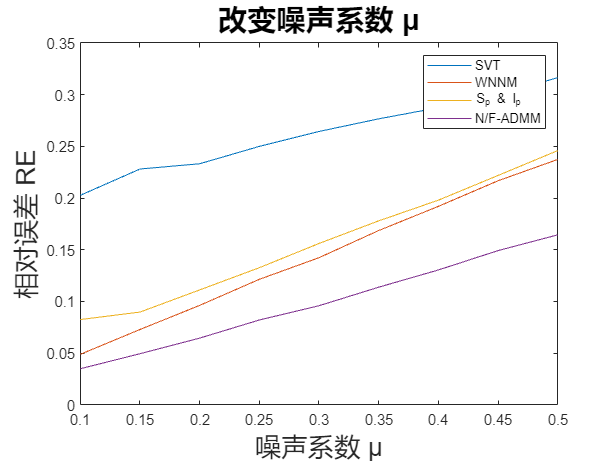

% % plot for mu (svt, wnnm, splp)
% plot(mu_vec, re_mu_svt_vec(:, 1))
% hold on
% plot(mu_vec, re_mu_wnnm_vec(:, 1))
% hold on
% plot(mu_vec, re_mu_splp_vec(:, 1))
% hold on
% plot(mu_vec, re_mu_nf_vec(:, 1))
% hold off
% title("改变噪声系数 μ")
% xlabel("噪声系数 μ")
% ylabel("相对误差 RE")
% legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
% saveas(gcf, 're-mu', 'jpg');
% plot for mu (svt, wnnm, splp)
plot(mu_vec, re_mu_svt_vec(:, 1))
hold on
plot(mu_vec, re_mu_wnnm_vec(:, 1))
hold on
plot(mu_vec, re_mu_splp_vec(:, 1))
hold on
plot(mu_vec, re_mu_nf_vec(:, 1))
hold off
title("改变噪声系数 μ","FontSize",20)
xlabel("噪声系数 μ","FontSize",18)
ylabel("相对误差 RE","FontSize",18)
legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
saveas(gcf, 're-mu-font', 'jpg');

plot for mu time

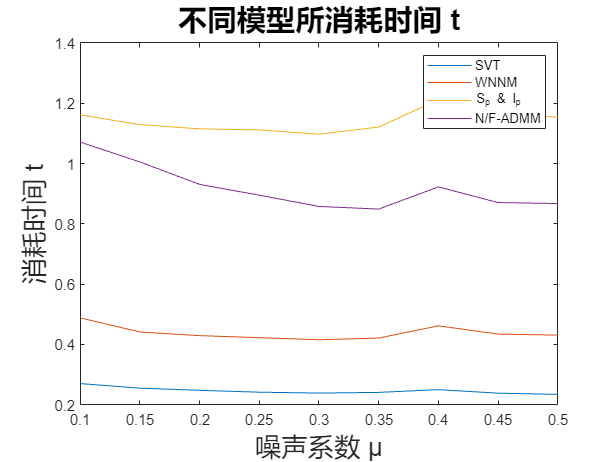

% plot(mu_vec, time_mu_svt_vec)
% hold on
% plot(mu_vec, time_mu_wnnm_vec)
% hold on
% plot(mu_vec, time_mu_splp_vec)
% hold on
% plot(mu_vec, time_mu_nf_vec)
% hold off
% title("不同模型所消耗时间 t")
% xlabel("噪声系数 μ")
% ylabel("消耗时间 t")
% legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
% saveas(gcf, 't-mu', 'jpg');
plot(mu_vec, time_mu_svt_vec)
hold on
plot(mu_vec, time_mu_wnnm_vec)
hold on
plot(mu_vec, time_mu_splp_vec)
hold on
plot(mu_vec, time_mu_nf_vec)
hold off
title("不同模型所消耗时间 t","FontSize",20)
xlabel("噪声系数 μ","FontSize",18)
ylabel("消耗时间 t","FontSize",18)
legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
saveas(gcf, 't-mu-font', 'jpg');

check the result of mu

re_mu_svt_vec

re_mu_svt_vec =     0.2026    0.0131
    0.2280    0.0091
    0.2331    0.0095
    0.2499    0.0095
    0.2643    0.0108
    0.2765    0.0086
    0.2873    0.0067
    0.2995    0.0139
    0.3164    0.0106


re_mu_wnnm_vec

re_mu_wnnm_vec =     0.0488    0.0025
    0.0728    0.0020
    0.0961    0.0030
    0.1214    0.0041
    0.1423    0.0035
    0.1685    0.0077
    0.1919    0.0052
    0.2167    0.0106
    0.2373    0.0115


re_mu_splp_vec

re_mu_splp_vec =     0.0824    0.0270
    0.0897    0.0215
    0.1111    0.0125
    0.1326    0.0072
    0.1560    0.0167
    0.1779    0.0104
    0.1979    0.0061
    0.2218    0.0093
    0.2458    0.0081


re_mu_nf_vec

re_mu_nf_vec =     0.0349    0.0016
    0.0494    0.0017
    0.0645    0.0018
    0.0820    0.0032
    0.0958    0.0022
    0.1137    0.0048
    0.1304    0.0035
    0.1491    0.0083
    0.1643    0.0076


2. change r

%% 2. change r
% re_r_**_vec stores the average value(re) of ** for different r(rank)
% 8 different ranks
re_r_svt_vec = zeros(8, 2);
re_r_wnnm_vec = zeros(8, 2);
re_r_splp_vec = zeros(8, 2);
re_r_nf_vec = zeros(8, 2);

% time
time_r_svt_vec = zeros(8, 1);
time_r_wnnm_vec = zeros(8, 1);
time_r_splp_vec = zeros(8, 1);
time_r_nf_vec = zeros(8, 1);

% index indicates the index of current r_change
index = 1;

% fun for different r_changes
for r_change = 6: 2: 20
    r_change
    index

    % define re_**_vec
    re_svt_vec = zeros(repeat, 1);
    re_wnnm_vec = zeros(repeat, 1);
    re_splp_vec = zeros(repeat, 1);
    re_nf_vec = zeros(repeat, 1);
    
    % repeat, return the vec
    for i = 1 : repeat
    
        % generating matrix
        L = normrnd(0, 1, n1, r_change);
        R = normrnd(0, 1, n2, r_change);
        N = normrnd(0, 1, n1, n2);
        X = L * R' + mu * N;
        
        % sampling matrix(support)
        support = ones(n1, n2);
        Ind = randperm(n1 * n2);
        
        %number of missing values
        EL0 = round(n1 * n2 * (1 - sr));
        
        %random EL0 elements would be set to 0
        support(Ind(1:EL0)) = 0;
    
        % observed matrix
        D = support .* X;
    
        % ||X||_F
        X_fro = max(norm(X, 'fro'), 1);
    
        %% SVT
        % svt parameters
        tao = sqrt(n1 * n2);
        step = 1.2 * sr;
    
        % experiment
        start_svt = tic;
        X_svt = SVT(D, support, tao, step, maxiter, tol);
        time_svt = toc(start_svt);
        % time
        time_r_svt_vec(index, 1) = time_r_svt_vec(index, 1) + time_svt;
    
        % re
        re_svt = norm(X_svt - X,'fro') / X_fro;
    
        % fill in the re_svt_vec
        re_svt_vec(i, 1) = re_svt;
    
        %% WNNM
        % wnnm parameters
        C = sqrt(n1 * n2);
    
        % experiment
        start_wnnm = tic;
        [A_WNNM, ~] = WNNM(D, support, C, eps, maxiter, tol);
        time_wnnm = toc(start_wnnm);
        % time
        time_r_wnnm_vec(index, 1) = time_r_wnnm_vec(index, 1) + time_wnnm;
    
        % re
        re_wnnm = norm(A_WNNM - X, 'fro') / X_fro;
    
        % fill in the re_wnnm_vec
        re_wnnm_vec(i, 1) = re_wnnm;
    
        %% Sp_lp
        % splp parameters
        % gamma = 1;
        % p1 = 0.1;
        % p2 = 0.2;

        % experiment
        start_splp = tic;
        X_splp = Sp_lp_new(D, support, gamma, p1, p2, maxiter, tol);
        time_splp = toc(start_splp);
        % time
        time_r_splp_vec(index, 1) = time_r_splp_vec(index, 1) + time_splp;

        % re
        re_splp = norm(X_splp - X, 'fro') / X_fro;

        % fill in the re_splp_vec
        re_splp_vec(i, 1) = re_splp;

        %% N/F
        % experiment
        start_nf = tic;
        X_nf = NF(D, support, lembda, mu1, mu2, k_max, t_max, tol_nf);
        time_nf = toc(start_nf);
        % time
        time_r_nf_vec(index, 1) = time_r_nf_vec(index, 1) + time_nf;

        % re
        re_nf = norm(X_nf - X, 'fro') / X_fro;

        %fill in the re_nf_vec
        re_nf_vec(i, 1) = re_nf;

    end

    % fill in the average re
    re_r_svt_vec(index, 1) = mean(re_svt_vec);
    re_r_wnnm_vec(index, 1) = mean(re_wnnm_vec);
    re_r_splp_vec(index, 1) = mean(re_splp_vec);
    re_r_nf_vec(index, 1) = mean(re_nf_vec);

    % fill in its std
    re_r_svt_vec(index, 2) = std(re_svt_vec);
    re_r_wnnm_vec(index, 2) = std(re_wnnm_vec);
    re_r_splp_vec(index, 2) = std(re_splp_vec);
    re_r_nf_vec(index, 2) = std(re_nf_vec);

    % normalization for time
    time_r_svt_vec(index, 1) = time_r_svt_vec(index, 1) / repeat;
    time_r_wnnm_vec(index, 1) = time_r_wnnm_vec(index, 1) / repeat;
    time_r_splp_vec(index, 1) = time_r_splp_vec(index, 1) / repeat;
    time_r_nf_vec(index, 1) = time_r_nf_vec(index, 1) / repeat;

    % update index
    index = index + 1;
end

r_change = 6

index = 1

r_change = 8

index = 2

r_change = 10

index = 3

r_change = 12

index = 4

r_change = 14

index = 5

r_change = 16

index = 6

r_change = 18

index = 7

r_change = 20

index = 8

plot for r (svt, wnnm, splp)

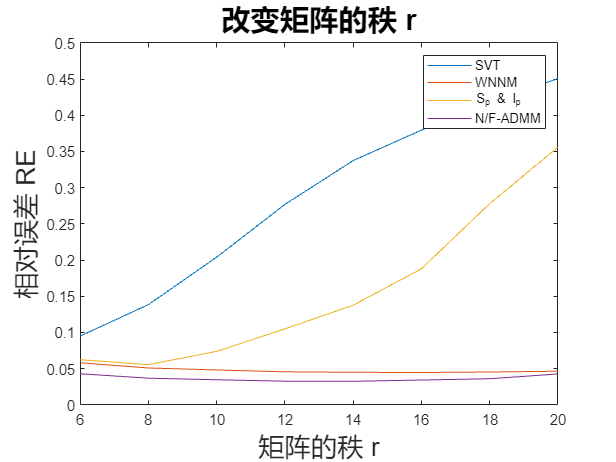

% % plot for r (svt, wnnm, splp)
% plot(r_vec, re_r_svt_vec(:, 1))
% hold on
% plot(r_vec, re_r_wnnm_vec(:, 1))
% hold on
% plot(r_vec, re_r_splp_vec(:, 1))
% hold on
% plot(r_vec, re_r_nf_vec(:, 1))
% hold off
% title("改变矩阵的秩 r")
% xlabel("矩阵的秩 r")
% ylabel("相对误差 RE")
% legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
% saveas(gcf, 're-r', 'jpg');
% plot for r (svt, wnnm, splp)
plot(r_vec, re_r_svt_vec(:, 1))
hold on
plot(r_vec, re_r_wnnm_vec(:, 1))
hold on
plot(r_vec, re_r_splp_vec(:, 1))
hold on
plot(r_vec, re_r_nf_vec(:, 1))
hold off
title("改变矩阵的秩 r","FontSize",20)
xlabel("矩阵的秩 r","FontSize",18)
ylabel("相对误差 RE","FontSize",18)
legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
saveas(gcf, 're-r-font', 'jpg');

plot for r time

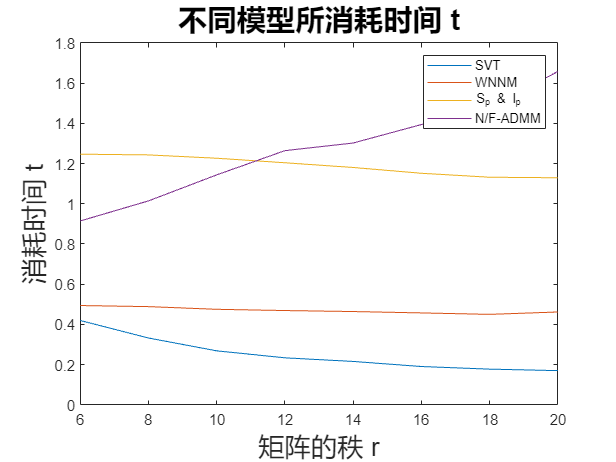

% plot(r_vec, time_r_svt_vec)
% hold on
% plot(r_vec, time_r_wnnm_vec)
% hold on
% plot(r_vec, time_r_splp_vec)
% hold on
% plot(r_vec, time_r_nf_vec)
% hold off
% title("不同模型所消耗时间 t")
% xlabel("矩阵的秩 r")
% ylabel("消耗时间 t")
% legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
% saveas(gcf, 't-r', 'jpg');
plot(r_vec, time_r_svt_vec)
hold on
plot(r_vec, time_r_wnnm_vec)
hold on
plot(r_vec, time_r_splp_vec)
hold on
plot(r_vec, time_r_nf_vec)
hold off
title("不同模型所消耗时间 t","FontSize",20)
xlabel("矩阵的秩 r","FontSize",18)
ylabel("消耗时间 t","FontSize",18)
legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
saveas(gcf, 't-r-font', 'jpg');

check

re_r_svt_vec

re_r_svt_vec =     0.0951    0.0086
    0.1385    0.0092
    0.2040    0.0150
    0.2769    0.0224
    0.3374    0.0072
    0.3794    0.0117
    0.4179    0.0054
    0.4506    0.0045


re_r_wnnm_vec

re_r_wnnm_vec =     0.0580    0.0028
    0.0509    0.0028
    0.0482    0.0021
    0.0456    0.0013
    0.0449    0.0015
    0.0446    0.0018
    0.0453    0.0017
    0.0464    0.0017


re_r_splp_vec

re_r_splp_vec =     0.0623    0.0032
    0.0555    0.0078
    0.0739    0.0207
    0.1049    0.0257
    0.1376    0.0250
    0.1879    0.0191
    0.2776    0.0293
    0.3557    0.0165


re_r_nf_vec

re_r_nf_vec =     0.0429    0.0025
    0.0368    0.0017
    0.0346    0.0019
    0.0327    0.0012
    0.0325    0.0007
    0.0342    0.0011
    0.0360    0.0020
    0.0426    0.0030


3. change sr

%% 3. change sr
% re_sr_**_vec stores the average value(re) of ** for different sr
% 9 below means there are 9 different srs
re_sr_svt_vec = zeros(9, 2);
re_sr_wnnm_vec = zeros(9, 2);
re_sr_splp_vec = zeros(9, 2);
re_sr_nf_vec = zeros(9, 2);

% time
time_sr_svt_vec = zeros(9, 1);
time_sr_wnnm_vec = zeros(9, 1);
time_sr_splp_vec = zeros(9, 1);
time_sr_nf_vec = zeros(9, 1);

% index indicates the index of current sr_change
index = 1;

% fun for different sr_changes
for sr_change = 0.5: 0.05: 0.9
    sr_change
    index

    % define re_**_vec
    re_svt_vec = zeros(repeat, 1);
    re_wnnm_vec = zeros(repeat, 1);
    re_splp_vec = zeros(repeat, 1);
    re_nf_vec = zeros(repeat, 1);
    
    % repeat, return the vec
    for i = 1 : repeat
    
        % generating matrix
        L = normrnd(0, 1, n1, r);
        R = normrnd(0, 1, n2, r);
        N = normrnd(0, 1, n1, n2);
        X = L * R' + mu * N;
        
        % sampling matrix(support)
        support = ones(n1, n2);
        Ind = randperm(n1 * n2);
        
        %number of missing values
        EL0 = round(n1 * n2 * (1 - sr_change));
        
        %random EL0 elements would be set to 0
        support(Ind(1:EL0)) = 0;
    
        % observed matrix
        D = support .* X;
    
        % ||X||_F
        X_fro = max(norm(X, 'fro'), 1);
    
        %% SVT
        % svt parameters
        tao = sqrt(n1 * n2);
        step = 1.2 * sr_change;
    
        % experiment
        start_svt = tic;
        X_svt = SVT(D, support, tao, step, maxiter, tol);
        time_svt = toc(start_svt);
        % time
        time_sr_svt_vec(index, 1) = time_sr_svt_vec(index, 1) + time_svt;
    
        % re
        re_svt = norm(X_svt - X,'fro') / X_fro;
    
        % fill in the re_svt_vec
        re_svt_vec(i, 1) = re_svt;
    
        %% WNNM
        % wnnm parameters
        C = sqrt(n1 * n2);
    
        % experiment
        start_wnnm = tic;
        [A_WNNM, ~] = WNNM(D, support, C, eps, maxiter, tol);
        time_wnnm = toc(start_wnnm);
        % time
        time_sr_wnnm_vec(index, 1) = time_sr_wnnm_vec(index, 1) + time_wnnm;
    
        % re
        re_wnnm = norm(A_WNNM - X, 'fro') / X_fro;
    
        % fill in the re_wnnm_vec
        re_wnnm_vec(i, 1) = re_wnnm;
    
        %% Sp_lp
        % splp parameters
        % gamma = 1;
        % p1 = 0.1;
        % p2 = 0.2;

        % experiment
        start_splp = tic;
        X_splp = Sp_lp_new(D, support, gamma, p1, p2, maxiter, tol);
        time_splp = toc(start_splp);
        % time
        time_sr_splp_vec(index, 1) = time_sr_splp_vec(index, 1) + time_splp;

        % re
        re_splp = norm(X_splp - X, 'fro') / X_fro;

        % fill in the re_splp_vec
        re_splp_vec(i, 1) = re_splp;

        %% N/F
        % experiment
        start_nf = tic;
        X_nf = NF(D, support, lembda, mu1, mu2, k_max, t_max, tol_nf);
        time_nf = toc(start_nf);
        % time
        time_sr_nf_vec(index, 1) = time_sr_nf_vec(index, 1) + time_nf;

        % re
        re_nf = norm(X_nf - X, 'fro') / X_fro;

        %fill in the re_nf_vec
        re_nf_vec(i, 1) = re_nf;

    end

    % fill in the average re
    re_sr_svt_vec(index, 1) = mean(re_svt_vec);
    re_sr_wnnm_vec(index, 1) = mean(re_wnnm_vec);
    re_sr_splp_vec(index, 1) = mean(re_splp_vec);
    re_sr_nf_vec(index, 1) = mean(re_nf_vec);

    % fill in ites std
    re_sr_svt_vec(index, 2) = std(re_svt_vec);
    re_sr_wnnm_vec(index, 2) = std(re_wnnm_vec);
    re_sr_splp_vec(index, 2) = std(re_splp_vec);
    re_sr_nf_vec(index, 2) = std(re_nf_vec);

    % normalization for time
    time_sr_svt_vec(index, 1) = time_sr_svt_vec(index, 1) / repeat;
    time_sr_wnnm_vec(index, 1) = time_sr_wnnm_vec(index, 1) / repeat;
    time_sr_splp_vec(index, 1) = time_sr_splp_vec(index, 1) / repeat;
    time_sr_nf_vec(index, 1) = time_sr_nf_vec(index, 1) / repeat;

    % update index
    index = index + 1;
end

sr_change = 0.5000

index = 1

sr_change = 0.5500

index = 2

sr_change = 0.6000

index = 3

sr_change = 0.6500

index = 4

sr_change = 0.7000

index = 5

sr_change = 0.7500

index = 6

sr_change = 0.8000

index = 7

sr_change = 0.8500

index = 8

sr_change = 0.9000

index = 9

plot for sr (svt, wnnm, splp)

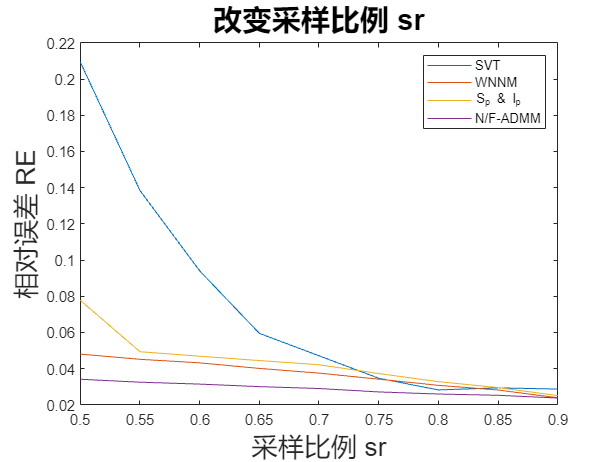

% plot(sr_vec, re_sr_svt_vec(:, 1))
% hold on
% plot(sr_vec, re_sr_wnnm_vec(:, 1))
% hold on
% plot(sr_vec, re_sr_splp_vec(:, 1))
% hold on
% plot(sr_vec, re_sr_nf_vec(:, 1))
% hold off
% title("改变采样比例 sr")
% xlabel("采样比例 sr")
% ylabel("相对误差 RE")
% legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
% saveas(gcf, 're-sr', 'jpg');
plot(sr_vec, re_sr_svt_vec(:, 1))
hold on
plot(sr_vec, re_sr_wnnm_vec(:, 1))
hold on
plot(sr_vec, re_sr_splp_vec(:, 1))
hold on
plot(sr_vec, re_sr_nf_vec(:, 1))
hold off
title("改变采样比例 sr","FontSize",20)
xlabel("采样比例 sr","FontSize",18)
ylabel("相对误差 RE","FontSize",18)
legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
saveas(gcf, 're-sr-font', 'jpg');

plot for sr time

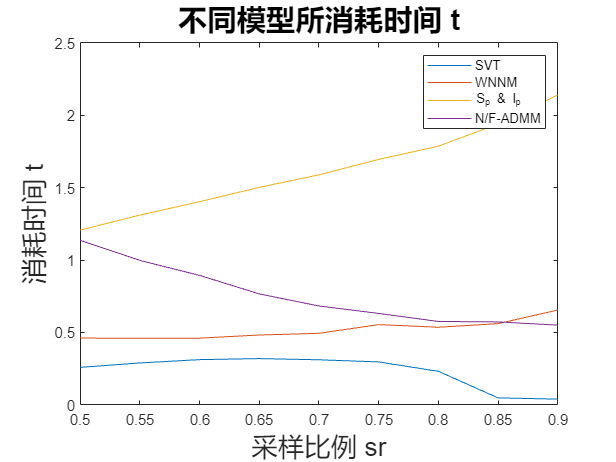

% plot(sr_vec, time_sr_svt_vec)
% hold on
% plot(sr_vec, time_sr_wnnm_vec)
% hold on
% plot(sr_vec, time_sr_splp_vec)
% hold on
% plot(sr_vec, time_sr_nf_vec)
% hold off
% title("不同模型所消耗时间 t")
% xlabel("采样比例 sr")
% ylabel("消耗时间 t")
% legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
% saveas(gcf, 't-sr', 'jpg');
plot(sr_vec, time_sr_svt_vec)
hold on
plot(sr_vec, time_sr_wnnm_vec)
hold on
plot(sr_vec, time_sr_splp_vec)
hold on
plot(sr_vec, time_sr_nf_vec)
hold off
title("不同模型所消耗时间 t","FontSize",20)
xlabel("采样比例 sr","FontSize",18)
ylabel("消耗时间 t","FontSize",18)
legend("SVT", "WNNM", "S_p & l_p", "N/F-ADMM")
saveas(gcf, 't-sr-font', 'jpg');

check

re_sr_svt_vec

re_sr_svt_vec =     0.2094    0.0139
    0.1384    0.0067
    0.0940    0.0086
    0.0595    0.0043
    0.0471    0.0045
    0.0347    0.0028
    0.0282    0.0016
    0.0294    0.0014
    0.0287    0.0005


re_sr_wnnm_vec

re_sr_wnnm_vec =     0.0480    0.0018
    0.0451    0.0017
    0.0432    0.0013
    0.0401    0.0012
    0.0375    0.0015
    0.0342    0.0011
    0.0308    0.0013
    0.0282    0.0012
    0.0239    0.0007


re_sr_splp_vec

re_sr_splp_vec =     0.0777    0.0244
    0.0493    0.0070
    0.0469    0.0013
    0.0444    0.0015
    0.0421    0.0018
    0.0373    0.0016
    0.0328    0.0012
    0.0295    0.0012
    0.0251    0.0009


re_sr_nf_vec

re_sr_nf_vec =     0.0341    0.0011
    0.0325    0.0011
    0.0314    0.0009
    0.0300    0.0012
    0.0290    0.0011
    0.0271    0.0013
    0.0260    0.0015
    0.0253    0.0016
    0.0237    0.0007
